## **Projet MT5: Commande d'un avion à décollage vertical**

**Stewart ANTOLINEZ - Enzo DELPY**

### 1. Modèle et hypothèses

Ce projet s'intéresse à la commande d'un avion à décollage et atterrissage verticaux (VTOL) en mode de vol stationnaire (hovering). L'objectif est de mettre en œuvre différentes stratégies de commande permettant à l'avion de suivre une trajectoire de référence, notamment lors d'une manœuvre d'approche à l'atterrissage.

Il est considéré que l'avion se déplace dans un plan vertical, avec $x$ et $z$ représentant la position de son centre de masse et $\theta$ son angle par rapport à l'horizontale. En notant $F_1$ et $F_2$ les poussées des deux réacteurs, le modèle dynamique s'écrit :


$$m\ddot{x}=(F_1-F_2)\sin\alpha\cos\theta-(F_1+F_2)\cos\alpha\sin\theta+f_x(\dot{x},\dot{z},\theta,\dot{\theta})
\\
m\ddot{z}=(F_1-F_2)\sin\alpha\sin\theta+(F_1+F_2)\cos\alpha\cos\theta-mg +f_z(\dot{x},\dot{z},\theta,\dot{\theta})
\\
J\ddot{\theta}=L(F_1-F_2)\cos\alpha+f_\theta(\dot{x},\dot{z},\theta,\dot{\theta})$$


Ces équations constituent la dynamique de translation horizontale, la dynamique de translation verticale et la dynamique de rotation de l'avion. Les termes en $(F_1+F_2)$ correspondent à la poussée totale des réacteurs, tandis que les termes en $(F_1-F_2)$ traduisent l'effet de leur différence. La projection des poussées sur les axes horizontal et vertical dépend de l'orientation $\theta$ de l'avion et de l'inclinaison $\alpha$ des réacteurs. Le terme $mg$ représente le poids du véhicule, et $J$ son moment d'inertie.

Les fonctions $f_x$, $f_z$ et $f_\theta$ représentent les effets aérodynamiques. Comme ceux-ci sont supposés faibles en mode *hovering*, ils sont négligés lors de la conception des lois de commande :


$$f_x=f_z=f_\theta=0$$


La dynamique des réacteurs est décrite par :


$$\dot{F}_1=\lambda(u_1-F_1)
\\
\dot{F}_2=\lambda(u_2-F_2)$$


Où $u_1$ et $u_2$ sont les commandes des réacteurs et $\lambda$ caractérise leur rapidité. Cette dynamique étant supposée rapide devant celle du véhicule, on considère, pour le calcul des lois de commande, que les poussées atteignent instantanément leurs valeurs de consigne :


$$F_1=u_1\qquad F_2=u_2$$


Cette approximation est utilisée uniquement pour la conception des commandes, en introduisant les variables de commande


$$\varepsilon=\frac{J}{mL}\tan\alpha \qquad
a=\frac{m}{\cos\alpha} \qquad
b=\frac{J}{L\cos\alpha} \qquad
v_1=\frac{F_1+F_2}{a} \qquad
v_2=\frac{F_1-F_2}{b}$$



$$
g=10\qquad
a=10000\qquad
b=10000\qquad
\varepsilon=0.1\qquad
\lambda=20
$$


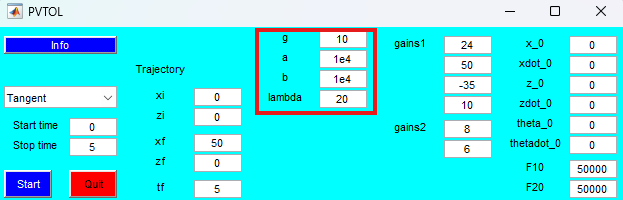

Cette représentation permet de distinguer les effets des deux commandes : $v_1$, associée à la poussée totale, agit principalement sur la translation, tandis que $v_2$, associée à la différence des poussées, commande directement l'accélération angulaire. Le couplage entre les mouvements de translation et de rotation apparaît à travers l'angle $\theta$.


$$\ddot{x}=\epsilon v_2\cos\theta-v_1\sin\theta
\\
\ddot{z}=\epsilon v_2\sin\theta+v_1\cos\theta-g
\\
\ddot{\theta}=v_2$$


### 2. Commande Linéaire

En théorie de la commande des systèmes non linéaires, un point d'équilibre est un état (\xi_e) associé à une entrée constante (u_e), pour lequel toutes les dérivées temporelles des états sont nulles. Pour un système décrit par


$$\dot{\xi}=f(\xi,u) \Rightarrow \text{condition d'équilibre} \Rightarrow f(\xi_e,u_e)=0$$


Dans le cas du VTOL étudié, un point d'équilibre correspond à une situation de vol stationnaire dans laquelle le véhicule conserve une position et une orientation constantes, sans vitesse ni accélération. Les poussées des réacteurs doivent alors compenser le poids du véhicule.

À partir du modèle normalisé, en négligeant les effets aérodynamiques, on considère le système suivant :


$$\ddot{x}=\epsilon v_2\cos\theta-v_1\sin\theta
\\
\ddot{z}=\epsilon v_2\sin\theta+v_1\cos\theta-g
\\
\ddot{\theta}=v_2$$


Le vecteur d’état et le vecteur de commande sont défini comme $\xi = [x, \dot{x}, z, \dot{z}, \theta, \dot{\theta}]^T$ et $$u = [v_1, v_2]^T$$.

Pour déterminer les points d'équilibre, il faut imposee l'annulation des dérivées des états :


$$\dot{x}_e=\ddot{x}_e=0\qquad
\dot{z}_e=\ddot{z}_e=0\qquad
\dot{\theta}_e=\ddot{\theta}_e=0$$


En substituant ces conditions dans le modèle dynamique:


$$0=\epsilon v_{2e}\cos\theta_e
-v_{1e}\sin\theta_e\\
0=\epsilon v_{2e}\sin\theta_e
+v_{1e}\cos\theta_e-g\\
0=v_{2e} \Leftarrow \text{impose directement}$$
    
$$\Rightarrow$$
 
$$0=v_{2e}$$
 
$$\Rightarrow$$
       
$$v_{1e}\cos\theta_e=g \Leftarrow  g\neq 0 \Rightarrow  v_{1e}\neq 0 \\
v_{1e}\sin\theta_e=0 \Rightarrow \sin\theta_e=0 \Rightarrow \theta_e=k\pi  \text { avec } k\in\mathbb{Z}$$


Pour un vol stationnaire avec une poussée totale positive, il maintient l'orientation horizontale $\theta_e=0$ modulo $2\pi$. Ainsi, $\cos\theta_e=1$ le système possède donc une famille de points d'équilibre caractérisés par une position arbitraire $(x_0,z_0)$, des vitesses nulles et les commandes constantes $v_{1e}=g$ et $v_{2e}=0$:


$$x_e=x_0 \qquad z_e=z_0 \qquad v_{1e}=g 
$$



$$\dot{x}_e=\dot{z}_e=\theta_e=\dot{\theta}_e= v_{2e}=0$$


Physiquement, la commande $v_{1e}=g$ permet de compenser le poids du véhicule, tandis que $v_{2e}=0$ garantit l'absence d'accélération angulaire. La position $(x_0,z_0)$ étant arbitraire, le modèle admet une infinité de points d'équilibre correspondant aux différentes positions possibles de vol stationnaire.

La linéarisation du modèle autour d'un point d'équilibre caractérisé par $\theta_e=0$, $v_{1e}=g$ et $v_{2e}=0$ est obtenue en introduisant les variables incrémentales par rapport à ce point d'équilibre. En utilisant les développements de Taylor au premier ordre et le modèle linéarisé tangent s'écrit:


$$\cos(\delta\theta)\approx 1
\qquad
\sin(\delta\theta)\approx\delta\theta$$



$$
\delta\ddot{x}=\epsilon\delta v_2-g\delta\theta 
\qquad
\delta\ddot{z}=\delta v_1
\qquad
\delta\ddot{\theta}=\delta v_2$$


Comme $\epsilon$ est petit, il est négligeable dans les équations, il est possible que $\delta x$ et $\delta z$ soient des sorties plates de ce système simplifié:

$\delta\ddot{x} = -g\delta\theta \Rightarrow \delta\theta = -\frac{1}{g}\delta\ddot{x} \\ \delta\ddot{\theta} = \delta v_2 $    $\Longrightarrow$    Dérivant deux fois $\delta x$ sachant que $$\delta\theta = -\frac{1}{g}\delta\ddot{x}$    $\Longrightarrow$    $\delta^{(4)}x = -g \delta\ddot{\theta} = -g \delta v_2$

Maintenant le VTOL va passer d'un position d'équilibre $(x=0, z=0, \theta=0)$ horizontalement à un autre point d'équilibre $(x=50,z=0,\theta=0)$

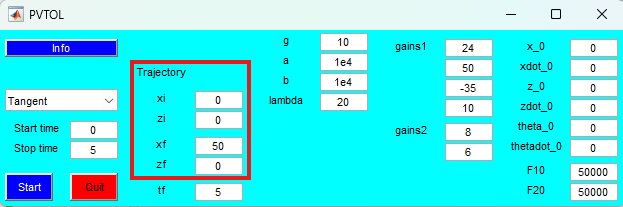

Donc la commande sera alors de la forme: 


$$\delta v_1 = \delta\ddot{z}_{\text{ref}} + k_1(\delta z_{\text{ref}} - \delta z) + k_2(\delta\dot{z}_{\text{ref}} - \delta\dot{z}) \\
\delta v_2 = -\frac{1}{g} \left( \delta x_{\text{ref}}^{(4)} + \ell_1(\delta x_{\text{ref}} - \delta x) + \ell_2(\delta\dot{x}_{\text{ref}} - \delta\dot{x}) + \ell_3(\delta\ddot{x}_{\text{ref}} - \delta\ddot{x}) + \ell_4(\delta^{(3)}x_{\text{ref}} - \delta^{(3)}x) \right)$$


Où les coefficients $k_1,k_2,\ell_1,\text{... ,}\ell_4$ sont calculés par placement de pôles.

Si le système linéarisé est complètement commandable, il est possible de placer les pôles en boucle fermée aux positions souhaitées dans le plan complexe, grâce à une loi de commande par retour d'état.

Pour le sous-système associé à $\delta z$, qui est d'ordre 2, on choisit un pôle double $p_0$. Le polynôme caractéristique désiré s'écrit :


$$(s-p_0)^2=s^2-2p_0s+p_0^2
=s^2+k_2s+k_1$$


Par identification des coefficients, on obtient :


$$k_1=p_0^2\qquad k_2=-2p_0$$


De même, pour le sous-système associé à $\delta x$, d'ordre 4, on choisit un pôle quadruple $p_0$. Le polynôme caractéristique désiré est alors :


$$(s-p_0)^4
=s^4-4p_0s^3+6p_0^2s^2-4p_0^3s+p_0^4=s^4+\ell_4s^3+\ell_3s^2+\ell_2s+\ell_1$$


Par identification des coefficients, les gains de retour d'état sont donnés par :


$$\ell_1 = p_0^4 \quad \ell_2 = -4p_0^3 \quad \ell_3 = 6p_0^2 \quad \ell_4 = -4p_0$$


clear; clc; close all;
p0 = -4;
k1 = p0^2;
k2 = -2*p0;
l1 = p0^4;
l2 = -4*p0^3;
l3 = 6*p0^2;
l4 = -4*p0;
fprintf('p0 = %d, k1 = %d, k2 = %d, l1 = %d, l2 = %d, l3 = %d, l4 = %d\n', p0, k1, k2, l1, l2, l3, l4);

p0 = -4, k1 = 16, k2 = 8, l1 = 256, l2 = 256, l3 = 96, l4 = 16


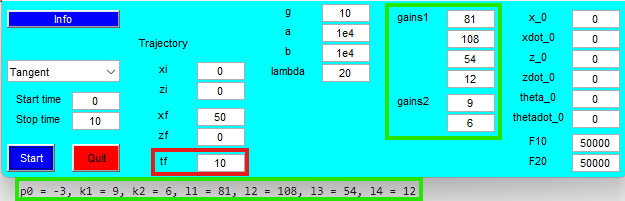

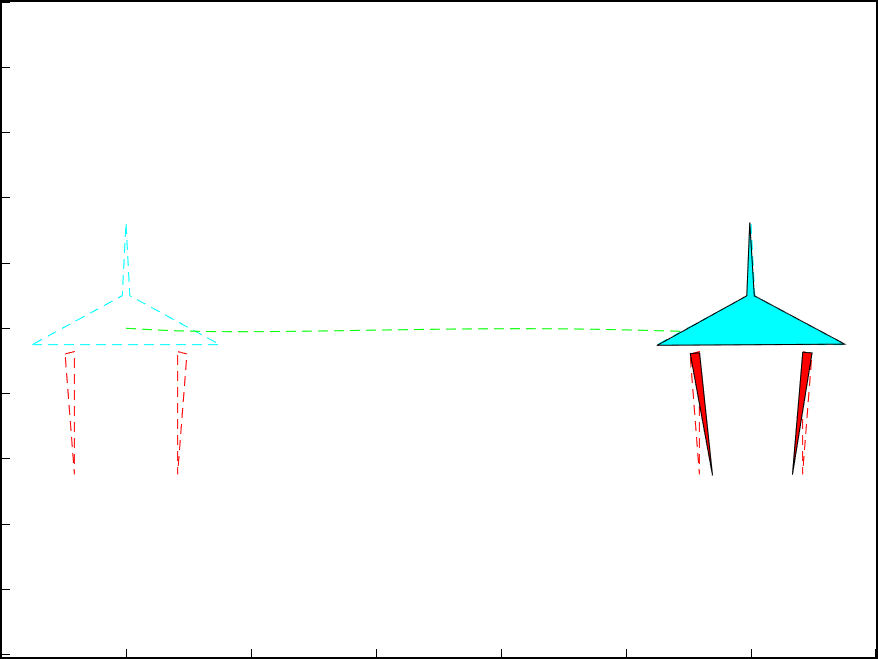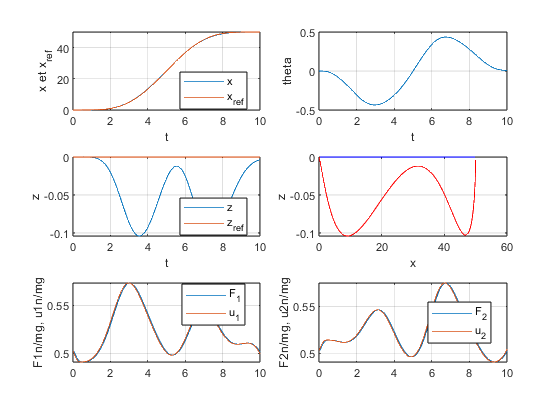

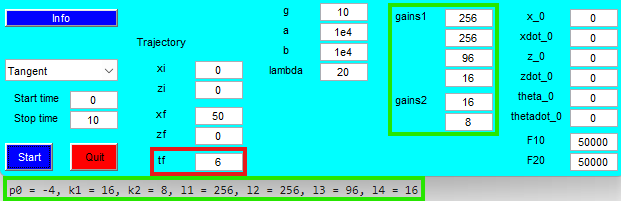

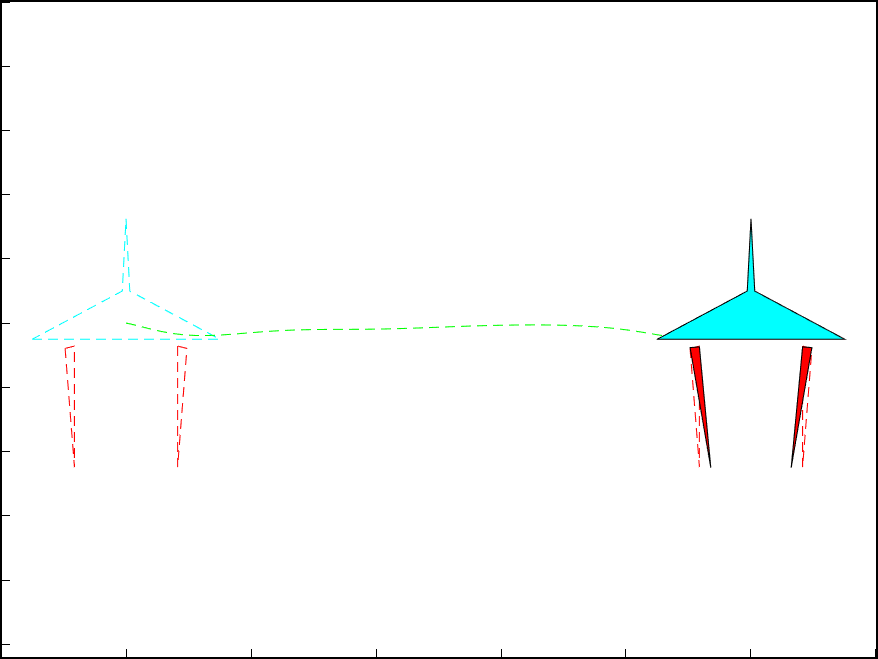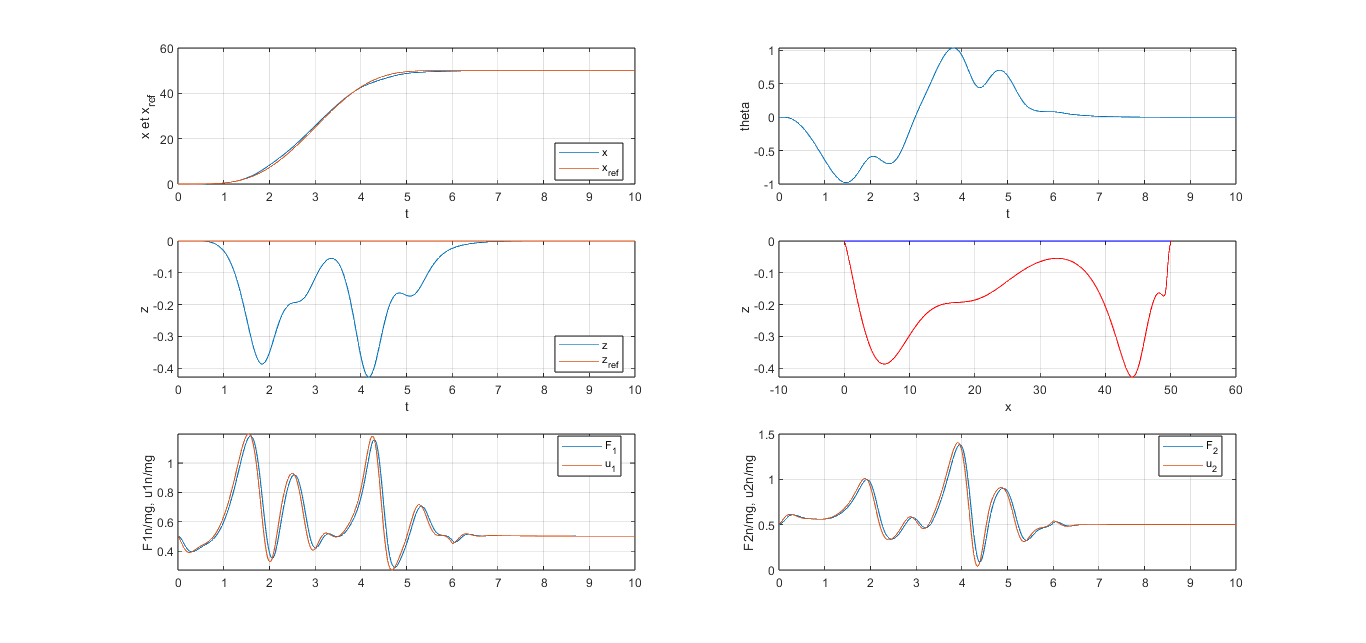

En faisant varier la valeur de $p_0$, ce qui modifie les gains de retour d'état, on observe que des gains plus élevés nécessitent généralement un temps de simulation plus long pour obtenir un comportement stable. De plus, pour obtenir un mouvement plus progressif de l'avion, il est nécessaire d'augmenter la durée finale de simulation $t_f$. Parmi les configurations testées, le résultat le plus rapide a été obtenu avec $p_0=-4$ et $t_f=6\text{s}$.

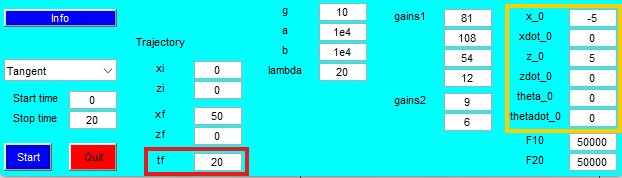

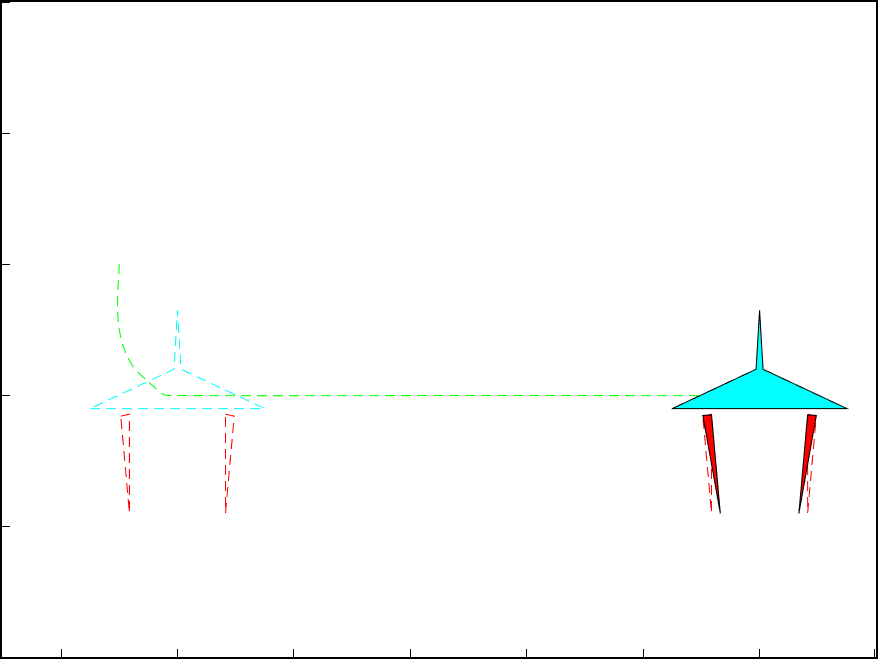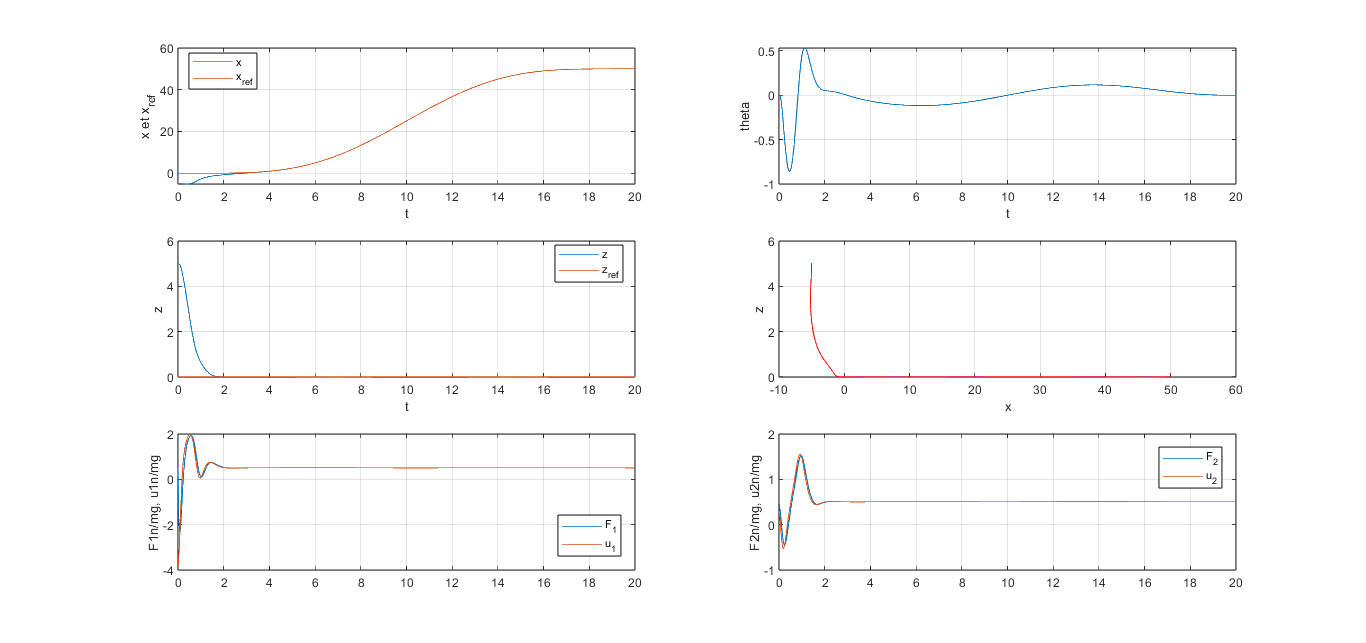

En présence de conditions initiales différentes du point d'équilibre, il est également nécessaire d'augmenter $t_f$ afin de laisser suffisamment de temps au système pour rejoindre la trajectoire de référence. Dans le cas contraire, l'erreur de suivi peut augmenter fortement et entraîner une divergence du système, qui ne parvient alors plus à suivre la référence.

### 3. Commande non-linéaire naïve

L'objectif de cette méthode est de découpler les dynamiques de translation afin d'obtenir deux systèmes indépendants vérifiant $\ddot{x}=w_1$ et $\ddot{z}=w_2$ où $w_1$ et $w_2$ sont des commandes auxiliaires. En substituant ces relations dans le modèle dynamique, on obtient le système algébrique suivant :


$$w_1=\epsilon v_2\cos\theta-v_1\sin\theta 
\qquad
w_2+g=\epsilon v_2\sin\theta+v_1\cos\theta$$


Ce système peut s'écrire sous forme matricielle $$A \cdot X = B$$ et en inversant la matrice $A$, finalement s'obtient $$X = A^{-1} \cdot B$$ et les commandes du système s'expriment alors en fonction des commandes auxiliaires:


$$\left\lbrack \begin{array}{cc}
-\sin \;\theta  & \epsilon \;\cos \;\theta \\
\cos \;\theta  & \epsilon \;\sin \;\theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_1 \\
v_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
w_1 \\
w_2 +g
\end{array}\right\rbrack \Longrightarrow \left\lbrack \begin{array}{c}
v_1 \\
v_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\sin \;\theta  & \cos \;\theta \\
\frac{\cos \;\theta }{\epsilon } & \frac{\sin \;\theta }{\epsilon }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w_1 \\
w_2 +g
\end{array}\right\rbrack \Longrightarrow$$

$$$$v_1 = (w_2 + g) \cos\theta - w_1 \sin\theta$$
$$v_2 = \frac{1}{\epsilon} \left( w_1 \cos\theta + (w_2 + g) \sin\theta \right)$$$$


Le découplage permet ainsi de concevoir séparément les lois de commande des deux axes de translation. Pour chaque axe, s'utilise une commande par retour d'état avec une action proportionnelle à l'erreur de position et une action proportionnelle à l'erreur de vitesse :


$$w_1=\ddot{x}{\mathrm{ref}}+k_1(x{\mathrm{ref}}-x)+k_2(\dot{x}{\mathrm{ref}}-\dot{x})\\
w_2=\ddot{z}{\mathrm{ref}}+\ell_1(z_{\mathrm{ref}}-z)+\ell_2(\dot{z}_{\mathrm{ref}}-\dot{z})$$


En imposant $$\ddot{x} = w_1$$ y $$\ddot{z} = w_2$$, l’équation de l’erreur de suivi pour l’axe $x$ est $$\ddot{e}_x + k_2 \dot{e}_x + k_1 e_x = 0$$ (avec $$e_x = x_{\text{ref}} - x$$).

Pour obtenir un comportement similaire sur les deux axes, on choisit un pôle double $p_0$ pour chaque sous-système d'ordre 2. Le polynôme caractéristique désiré est :


$$$$(s - p_0)^2 = s^2 - 2p_0 s + p_0^2 = s^2 + k_2 s + k_1$$$$


Par identification des coefficients, les gains sont déterminés par :


$$k_1=\ell_1=p_0^2\qquad
k_2=\ell_2=-2p_0$$


Bien que la linéarisation entrée-sortie permette de découpler les dynamiques de translation, elle ne garantit pas la stabilité de l'ensemble du système. Pour étudier ce comportement, il faut considèrer le cas où les sorties suivent une référence nulle, soit $x(t)=z(t)=0$. Dans cette situation, les commandes auxiliaires sont nulles $w_1=w_2=0$. En substituant ces conditions dans l'expression de $v_2$:

$v_2=\frac{g}{\epsilon}\sin\theta$    $\Longrightarrow$    dynamique de l'orientation: $\ddot{\theta}=v_2$    $\Longrightarrow$    $\ddot{\theta}=\frac{g}{\epsilon}\sin\theta$

Avec les valeurs numériques $g=10$ et $\epsilon=0.1$, cette équation devient $\ddot{\theta}=100\sin\theta$, en linéarisant autour de l'équilibre $\theta_e=0$, avec l'approximation $\sin\theta\approx\theta$, ce qui donne $\delta\ddot{\theta}=100 \cdot\delta\theta$, où le polynôme caractéristique associé est $s^2-100=0$, dont les valeurs propres sont:


$$s_1=10\qquad s_2=-10$$


La présence d'une valeur propre positive indique que l'équilibre $\theta_e=0$ de la dynamique interne est instable. Le système présente donc une dynamique de zéros instable, ce qui caractérise un comportement non à phase minimale.

clear; clc; close all;
p0 = -10;
k1 = p0^2;
l1 = p0^2;
k2 = -2*p0;
l2 = -2*p0;
fprintf('p0 = %d, k1 = %d, k2 = %d, l1 = %d, l2 = %d\n', p0, k1, k2, l1, l2);

p0 = -10, k1 = 100, k2 = 20, l1 = 100, l2 = 20


Cette instabilité explique les résultats insatisfaisants observés lors des essais de la stratégie commande non-linéaire naïve dans l'interface graphique. Même si les positions $x$ et $z$ suivent leur référence, l'angle $\theta$ peut diverger, entraînant une instabilité interne de l'avion.

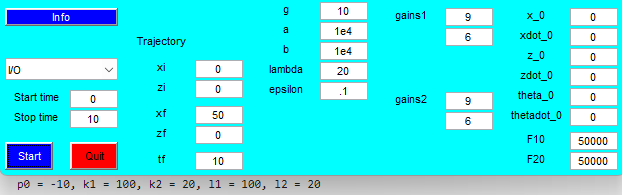

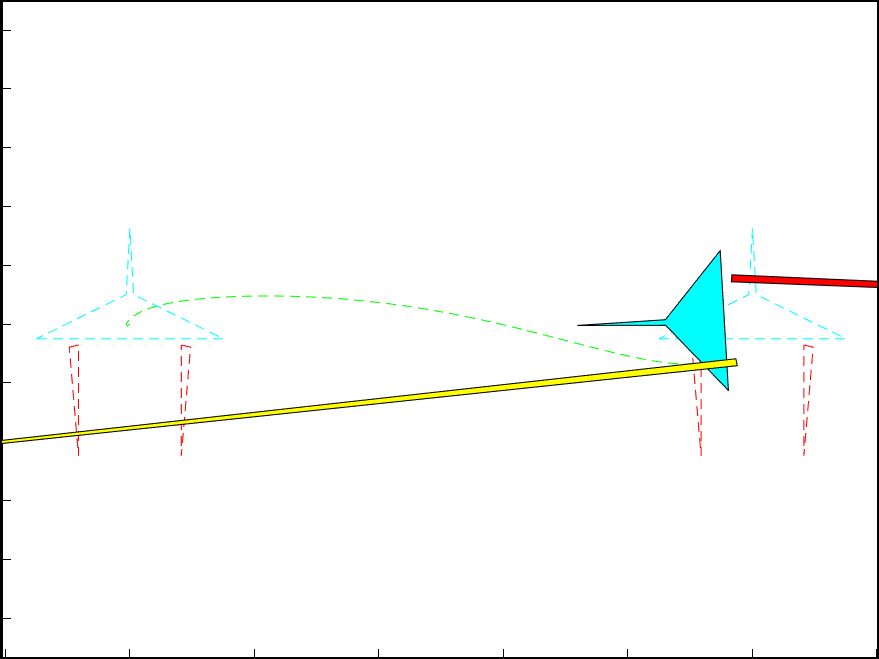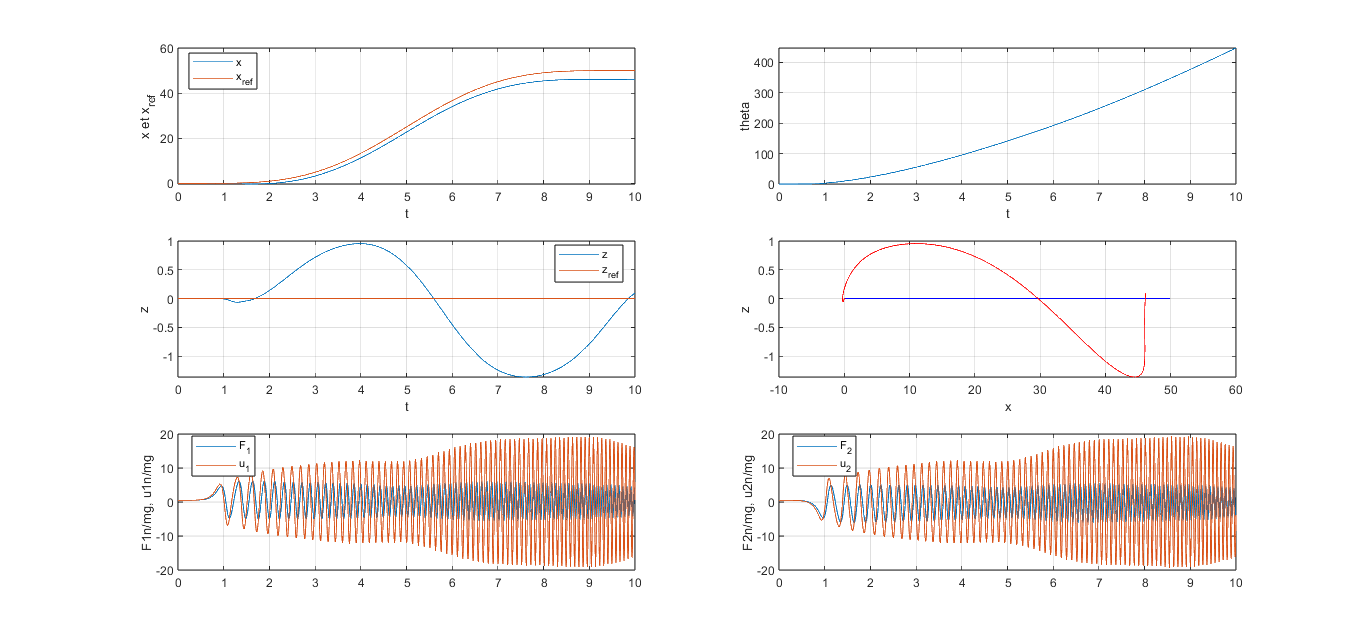

### 4. Commande non-linéaire par platitude

Pour montrer que le vecteur formé par $y_1$ et $y_2$ est une sortie plate du système, il faut démontrer que toutes les variables d'état et les commandes peuvent s'exprimer en fonction de ces sorties et de leurs dérivées successives.

Tout d'abord, rappeller les expressions des sorties plates : 


$$$$y_1 = x - \epsilon \sin\theta$$
$$y_2 = z + \epsilon \cos\theta$$$$


En dérivant deux fois ces sorties par rapport au temps à l'aide des équations du modèle de commande et en posant la variable intermédiaire


$$$$\ddot{y}_1 = \ddot{x} - \epsilon (\ddot{\theta}\cos\theta - \dot{\theta}^2\sin\theta)$$$$\ddot{y}_2 = \ddot{z} + \epsilon (-\ddot{\theta}\sin\theta - \dot{\theta}^2\cos\theta)$$$$

$$\Longrightarrow$$

$$\text{Remplacer la dynamique originale du système}\\
\ddot{x} = \epsilon v_2 \cos\theta - v_1 \sin\theta \qquad \ddot{z} = \epsilon v_2 \sin\theta + v_1 \cos\theta - g \qquad \ddot{\theta} = v_2$$

$$\Longrightarrow \ldotp \ldotp \ldotp$$



$$\ldotp \ldotp \ldotp \Longrightarrow$$

$$\ddot{y}_1 = (\epsilon v_2 \cos\theta - v_1 \sin\theta) - \epsilon v_2 \cos\theta + \epsilon \dot{\theta}^2 \sin\theta= -(v_1 - \epsilon \dot{\theta}^2) \sin\theta \\ \ddot{y}_2 = (\epsilon v_2 \sin\theta + v_1 \cos\theta - g) - \epsilon v_2 \sin\theta - \epsilon \dot{\theta}^2 \cos\theta = (v_1 - \epsilon \dot{\theta}^2) \cos\theta - g $$

$$\Longrightarrow$$

$$\text{avec}\\
\zeta(t) = v_1(t) - \epsilon \dot{\theta}^2(t)$$

$$\Longrightarrow$$

$$ \ddot{y}_1 = -\zeta \sin\theta \\ \ddot{y}_2 = \zeta \cos\theta  - g$$


Les positions $x$ et $z$ s'expriment alors directement à partir des sorties plates et de l'angle theta trouvé :


$$x = y1 + \epsilon  \cdot sin(\theta) \\z = y2 - \epsilon \cdot cos(\theta)$$


Enfin, les vitesses et les dérivées de l'angle s'obtiennent par dérivation successive, ce qui permet d'exprimer les commandes : 


$$v_2 = \ddot\theta \\
v_1 = \zeta + \epsilon \cdot \dot\theta^2$$

$$\Leftarrow$$
 
$$\text{avec: }
\tan\theta = -\frac{\ddot y_1}{\ddot{y_2} + g} \Rightarrow \theta = \arctan( \frac{-\ddot{y}_1}{\ddot{y}_2 + g} )$$


Puisque l'ensemble des états ($x, z, \theta$ et leurs dérivées) ainsi que les commandes $(v_1, v_2)$ s'expriment uniquement en fonction de $y_1, y_2$ et de leurs dérivées, le vecteur $(y_1, y_2)$ constitue bien une sortie plate.

Pour construire un contrôleur dynamique réalisant une linéarisation entrée-état du système. Pour cela, en dérivant quatre fois successivement les sorties plates  et par rapport au temps, et en posant la variable intermédiaire $\zeta(t) = v_1(t) - \epsilon \dot{\theta}^2(t)$ , le système découplé sous la forme:


$$y_1^{(4)} = \ddot{\zeta} (-\sin\theta) - 2\dot{\zeta}\dot{\theta}\cos\theta + \zeta\dot{\theta}^2\sin\theta - \zeta\ddot{\theta}\cos\theta \\ y_2^{(4)} = \ddot{\zeta} \cos\theta - 2\dot{\zeta}\dot{\theta}\sin\theta - \zeta\dot{\theta}^2\cos\theta - \zeta\ddot{\theta}\sin\theta$$

$$\Longrightarrow$$

$$$$y_1^{(4)} = w_1$$
$$y_2^{(4)} = w_2$$$$


La dynamique de la variable intermédiaire $\zeta(t)$vérifie une équation différentielle du second ordre. En posant les variables d'état $$\zeta_1 = \zeta$$ et $$\zeta_2 = \dot{\zeta}$$.

Les commandes réelles $v_1$ et $v_2$ à partir des commandes virtuelles $w_1,w_2$, de l'état $\zeta_1$, de l'angle $\theta$ et de sa dérivée $\dot\theta$, les commandes réelles s'expriment par :


$$v_1 = \zeta_1 + \epsilon \dot{\theta}^2\\
v_2 = \ddot{\theta} = \frac{1}{\zeta_1} \left( -w_1 \cos\theta - w_2 \sin\theta - 2 \zeta_2 \dot{\theta} \right)$$


Placement de pôles et expression des gains, en choisissant un pôle unique $p_0$ d'ordre 4 pour chacun des sous-systèmes, le polynôme caractéristique désiré est:


$$(s - p_0)^4 = s^4 - 4p_0s^3 + 6p_0^2s^2 - 4p_0^3s + p_0^4 = 0$$


Par identification avec le polynôme caractéristique du correcteur, les gains du retour d'état (pour les coefficients $\ell_i$et $k_i$) s'expriment en fonction de $p_0$ de la manière suivante:


$$$$\ell_1 = k_1 = p_0^4$$$$\ell_2 = k_2 = -4p_0^3$$$$\ell_3 = k_3 = 6p_0^2$$$$\ell_4 = k_4 = -4p_0$$$$


clear; clc; close all;
p0 = -3;
k1 = p0^4;
l1 = k1;
k2 = -4*p0^3;
l2 = k2;
k3 = 6*p0^2;
l3 = k3;
k4 = -4*p0;
l4 = k4;
fprintf('p0 = %d, k1 = l1 = %d, k2 = l2 = %d, k3 = l3 = %d, k4 = l4 = %d\n', p0, k1, k2, k3, k4);

p0 = -3, k1 = l1 = 81, k2 = l2 = 108, k3 = l3 = 54, k4 = l4 = 12


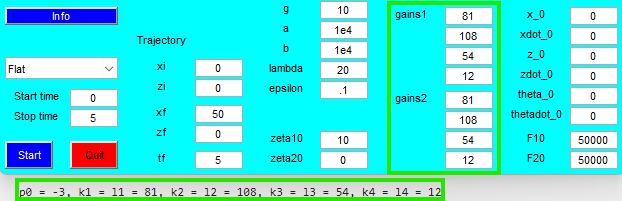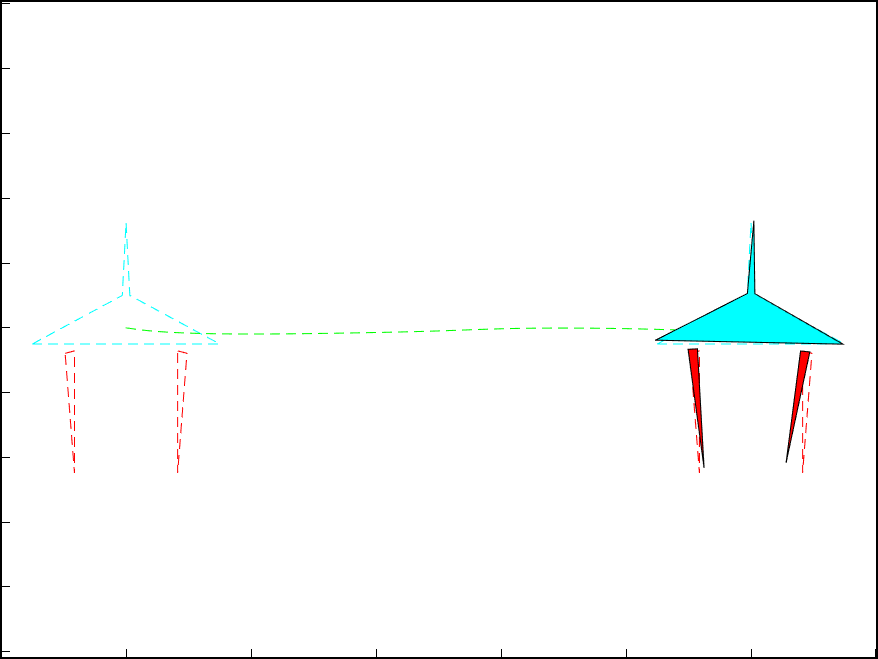

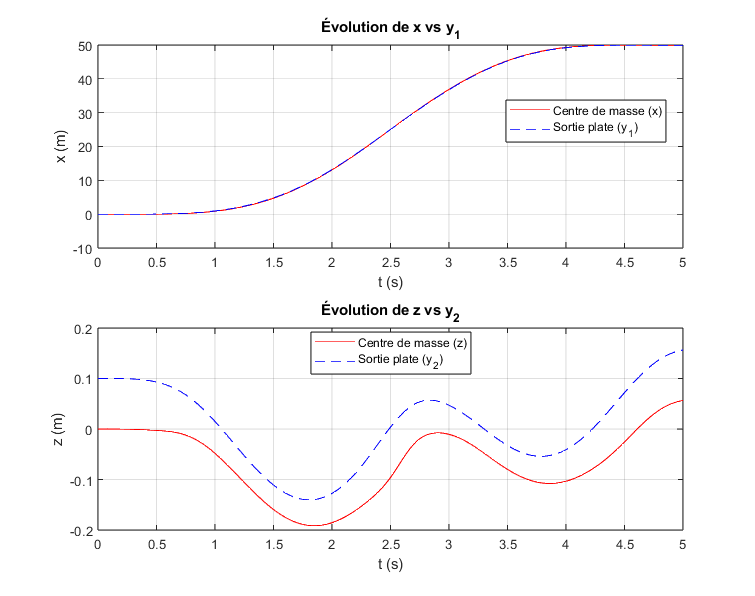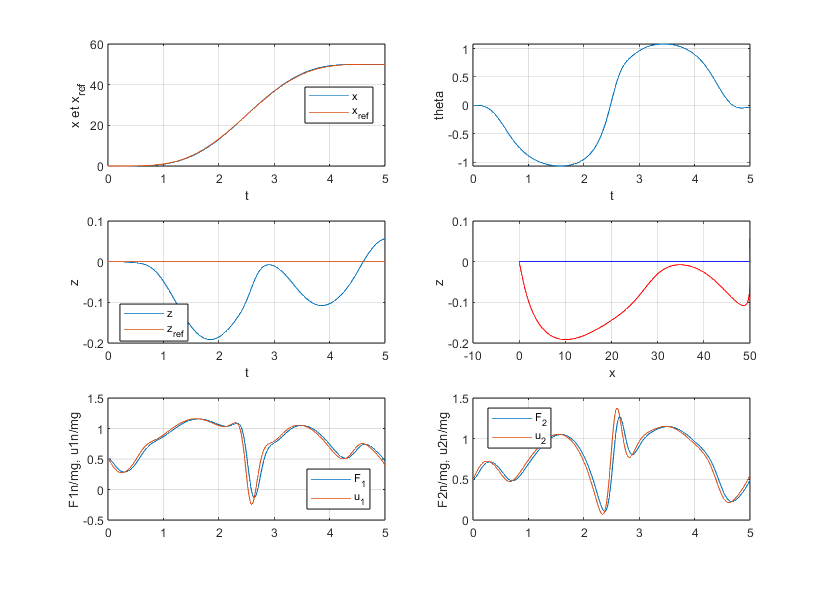

Pour le ficher *traj.m* les signaux de référence doivent être au moins quatre fois continûment dérivables ($C^4$) afin de fournir les dérivées successives requises jusqu'à l'ordre 4 ($$x_{ref}^{(4)}$ \text{ et } $z_{ref}^{(4)}$$) et d'éviter des impulsions de Dirac qui satureraient les actionneurs.

La linéarisation entrée-sortie naïve sur $(x,z)$ conduisait à un système non à phase minimum (dynamique des zéros instable), faisant diverger l'angle $\theta$. En revanche, l'approche par platitude choisit des sorties plates $(y_1,y_2)$ qui intègrent le couplage naturel de l'avion, assurant un découplage total et stable sans dynamique interne cachée.

**Mouvement de la sortie plate et du centre de masse :**

- **La sortie plate (**$y_1,y_2$**) :** suit parfaitement la trajectoire de référence sans erreur statique grâce au placement de pôles.

- **Le centre de masse (**$x,z$**) :** subit de légers transitoires et oscillations lors des phases d'accélération en raison du couplage géométrique avec l'inclinaison $\theta$, avant de converger vers la position finale.